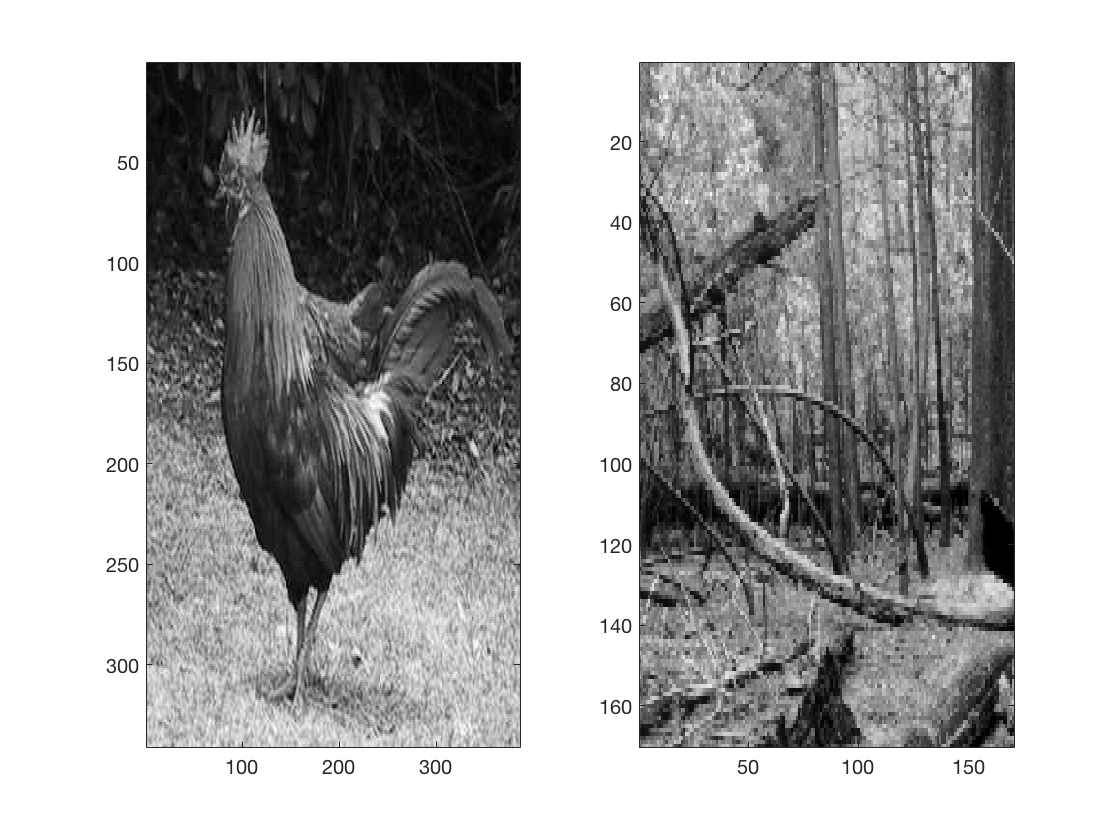

Ia=imread('rooster.jpg');
IaRbg=im2double(Ia);
Ia=rgb2gray(IaRbg);
Ib=imread('woods.png');
Ib=im2double(Ib);
Ic=imread('elephant.png');
Ic=im2double(Ic);
% original image
figure(11),subplot(1,2,1),imagesc(Ia);
subplot(1,2,2),imagesc(Ib);
colormap('gray')

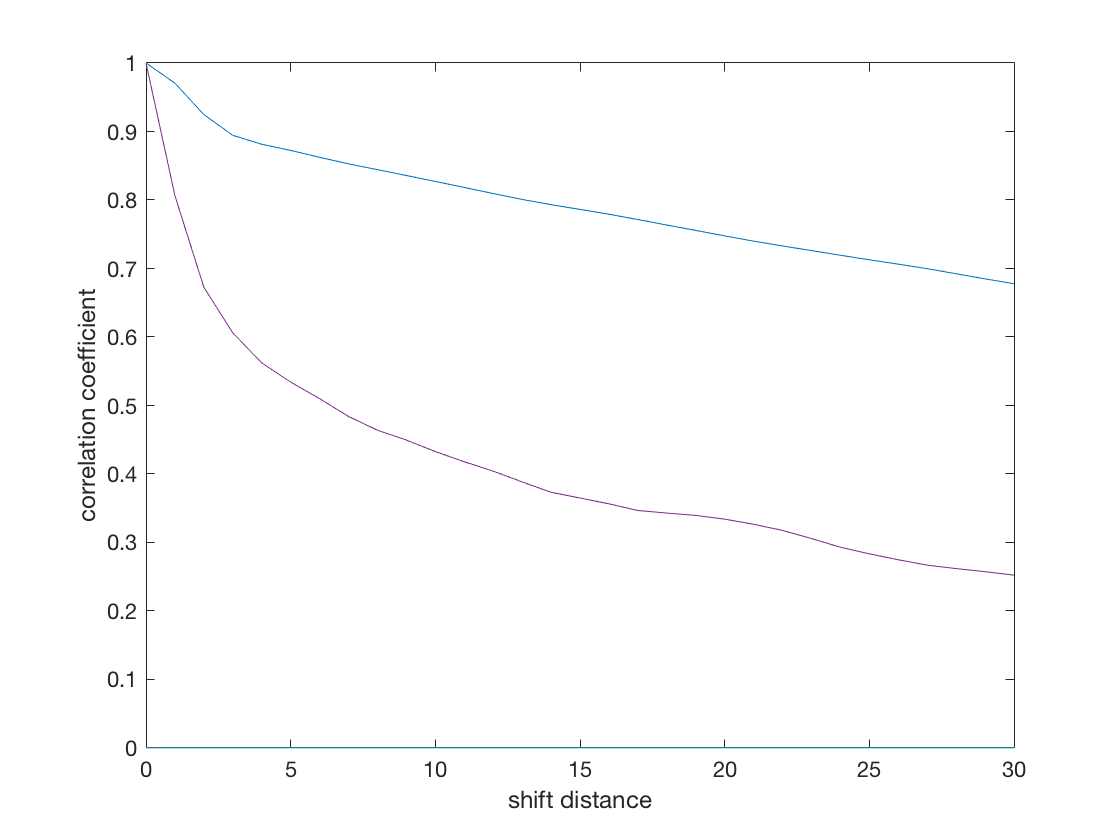


%% Question 2 Redundancy in Natural Images

corr2(Ia,Ia);
shiftsize=30;
x=0:1:shiftsize;
y1=corrShift(Ia,shiftsize);
y2=corrShift(Ib,shiftsize);
figure(1),plot(x,y1,x,y2),xlabel('shift distance'),ylabel('correlation coefficient');

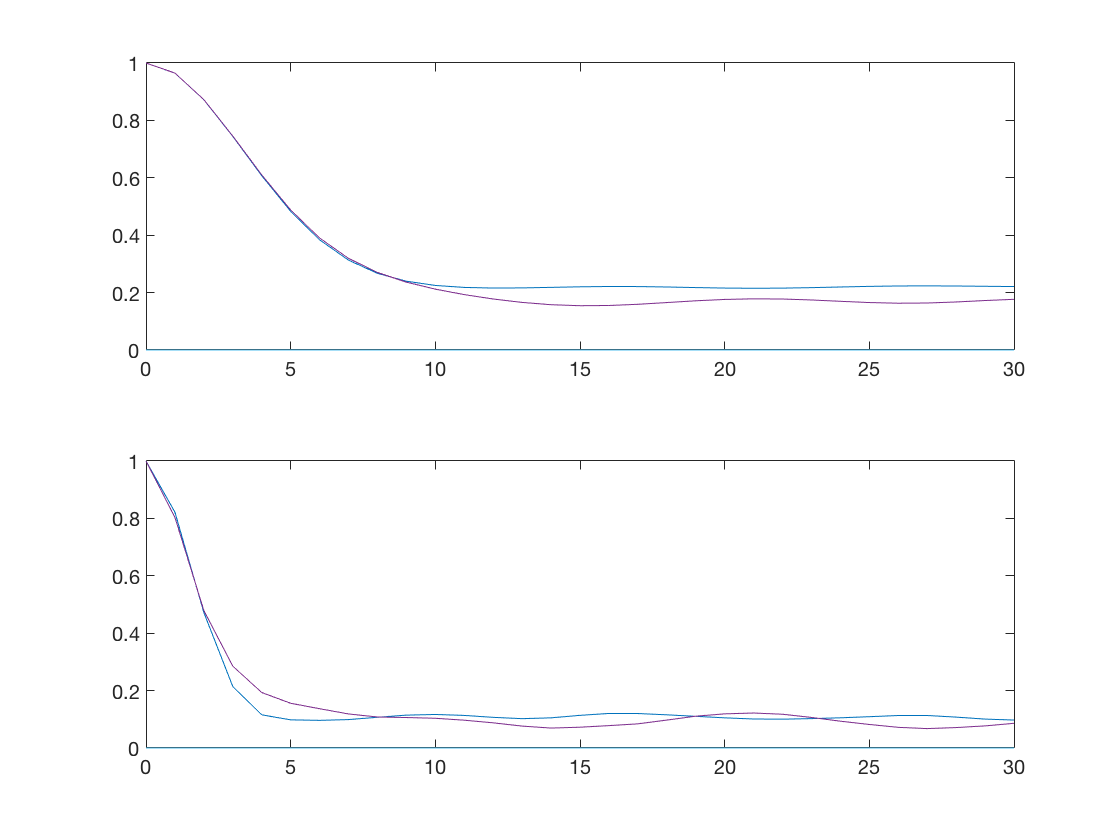

%% Question 3.1 Redundancy Reduction using DoG masks 
g1=fspecial('gaussian',[40,40],6);
g2=fspecial('gaussian',[40,40],2);
DoG=g2-g1;
IaDoG=conv2(Ia,DoG,'same');
y3=corrShift(IaDoG,shiftsize);
IbDoG=conv2(Ib,DoG,'same');
y4=corrShift(IbDoG,shiftsize);
figure(2),subplot(2,1,1),plot(x,y3,x,y4);


g3=fspecial('gaussian',[30,30],4);
g4=fspecial('gaussian',[30,30],0.5);
DoG2=g4-g3;
IaDoG2=conv2(Ia,DoG2,'same');
y5=corrShift(IaDoG2,shiftsize);
IbDoG2=conv2(Ib,DoG2,'same');
y6=corrShift(IbDoG2,shiftsize);
subplot(2,1,2),plot(x,y5,x,y6);

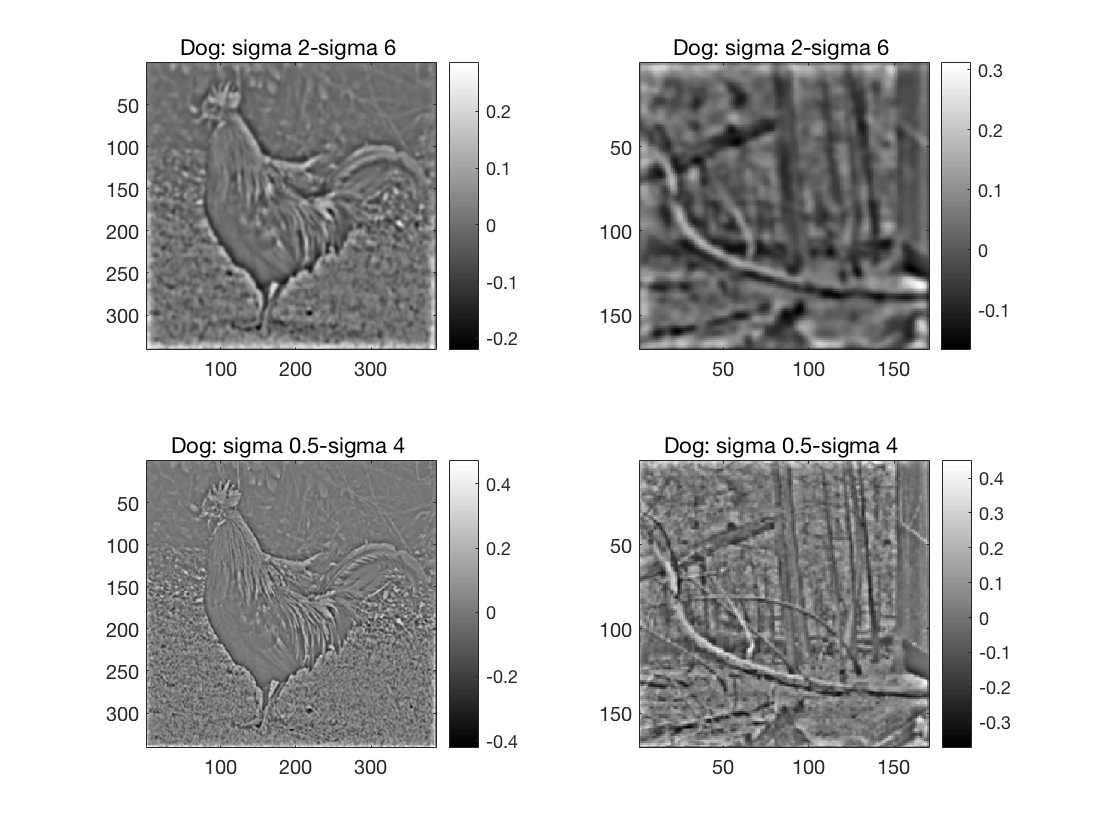

figure(23),subplot(2,2,1),imagesc(IaDoG);title('Dog: sigma 2-sigma 6 '),colorbar
subplot(2,2,2),imagesc(IbDoG);title('Dog: sigma 2-sigma 6 '),colorbar
subplot(2,2,3),imagesc(IaDoG2);title('Dog: sigma 0.5-sigma 4 '),colorbar
subplot(2,2,4),imagesc(IbDoG2);title('Dog: sigma 0.5-sigma 4 '),colorbar
colormap('gray')

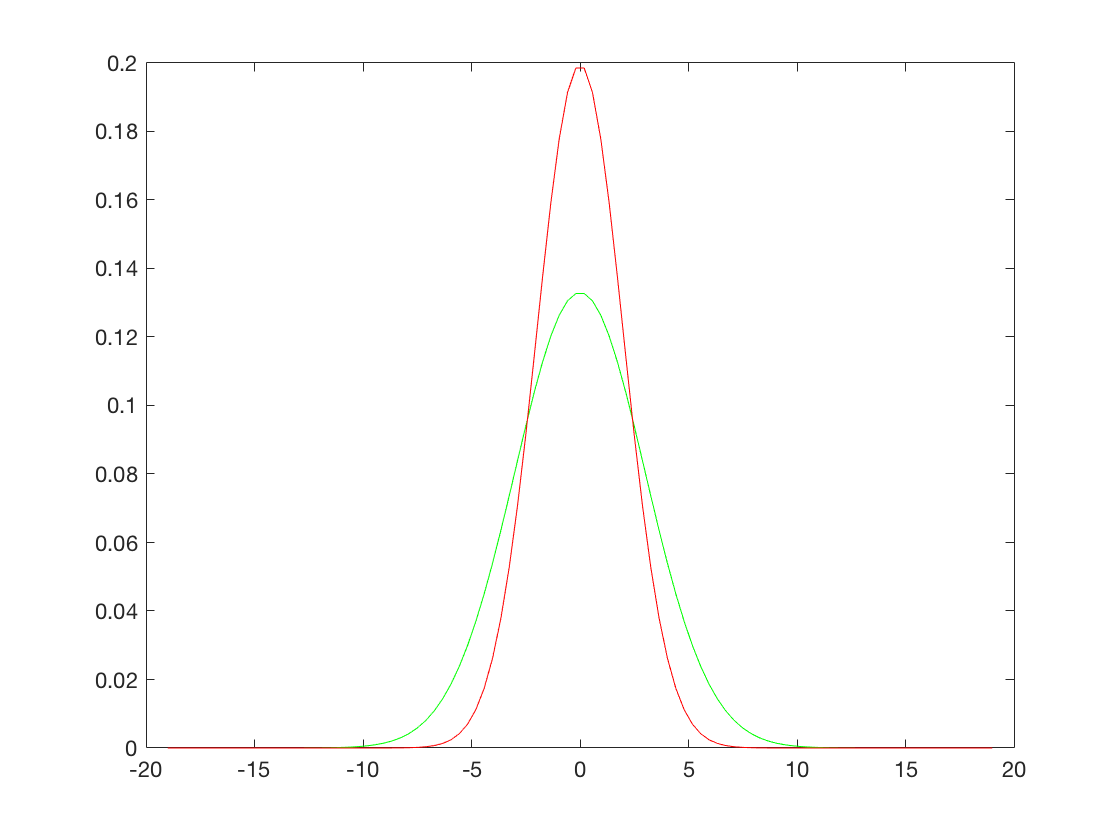


%}

x=linspace(-19,19);
y=normpdf(x,0,3);
figure(320)
plot(x,y,'g');
hold on
x2=linspace(-19,19);
y2=normpdf(x,0,2);
plot(x2,y2,'r');
hold on

% x3=linspace(-19,19);
% y3=normpdf(x,0,2);
% plot(x3,y3,'r');

function [y]=corrShift(Image,shiftsize)
y=zeros(shiftsize+1);
for shiftPosition=0:1:shiftsize
    shift=zeros(2*shiftsize+1);
    shift(shiftsize+1,shiftsize+1-shiftPosition)=1;
    ImageShift=conv2(Image,shift,'same');
    y(shiftPosition+1)=corr2(Image,ImageShift);
end
end